clc;
clear;
close all;

%% PARAMETERS
N = 1e4;              % Number of bits
Rb = 1e9;             % Bit rate
Fs = 10e9;            % Sampling frequency
samples_per_bit = Fs/Rb;

t = (0:N*samples_per_bit-1)/Fs;

% Different attenuation values (in dB)
atten_dB = [0 5 10 15 20];

BER = zeros(size(atten_dB));

%% TRANSMITTER

data = randi([0 1], 1, N);
nrz_signal = repelem(data, samples_per_bit);

P_tx = 1;
tx_signal = P_tx * nrz_signal;

%% LOOP OVER ATTENUATIONS

for k = 1:length(atten_dB)
    
    % Convert dB to linear scale
    att_linear = 10^(-atten_dB(k)/10);
    
    % Apply attenuation
    rx_signal = tx_signal * att_linear;
    
    % Add noise
    SNR_dB = 20;
    rx_signal = awgn(rx_signal, SNR_dB, 'measured');
    
    %% RECEIVER
    
    % Photodetection
    R = 1;
    elec_signal = R * rx_signal;
    
    % Low-pass filter
    Wn = (Rb)/(Fs/2);
    b = fir1(100, Wn);
    filtered = filter(b, 1, elec_signal);
    
    % Sampling
    samples = filtered(samples_per_bit:samples_per_bit:end);
    
    % Decision
    threshold = mean(samples);
    rx_bits = samples > threshold;
    
    % BER
    [~, BER(k)] = biterr(data, rx_bits);
    
    fprintf('Attenuation = %d dB, BER = %e\n', atten_dB(k), BER(k));
end

Attenuation = 0 dB, BER = 4.902000e-01
Attenuation = 5 dB, BER = 4.905000e-01
Attenuation = 10 dB, BER = 4.905000e-01
Attenuation = 15 dB, BER = 4.900000e-01
Attenuation = 20 dB, BER = 4.908000e-01


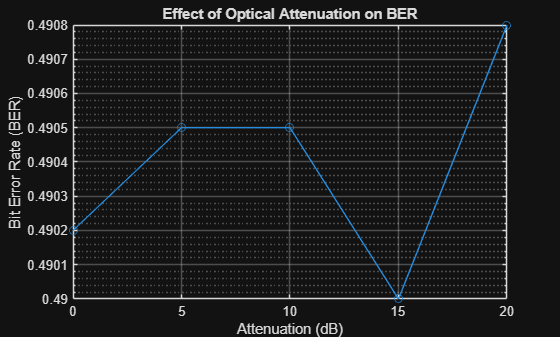


%% PLOT: BER vs Attenuation

figure;
semilogy(atten_dB, BER, '-o');
grid on;
xlabel('Attenuation (dB)');
ylabel('Bit Error Rate (BER)');
title('Effect of Optical Attenuation on BER');

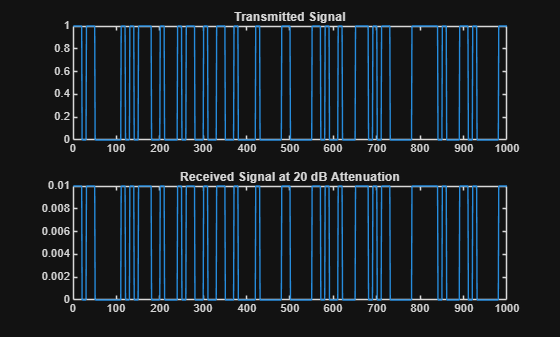


%% SIGNAL VISUALIZATION (for highest attenuation)

figure;

subplot(2,1,1);
plot(tx_signal(1:1000));
title('Transmitted Signal');

subplot(2,1,2);
rx_high = tx_signal * 10^(-atten_dB(end)/10);
plot(rx_high(1:1000));
title(['Received Signal at ', num2str(atten_dB(end)), ' dB Attenuation']);